# Using Widgets Toolbox

## Using Widgets 

Widgets may be instantiated and placed within a figure in the same way as MATLAB graphics objects, such as axes or uicontrol. The specific functionality of each widget is documented by examples, and by documentation within the code files themselves.

f = figure('Units','pixels','Position',[100 100 520 100]);

w = uiw.widget.FileSelector(...
    'Parent', f, ...
    'Pattern', {'*.mat','MATLAB MAT files (*.mat)'; '*.csv','CSV files (*.csv)'}, ...
    'Callback',@(h,e)disp(e),...
    'Label','Choose a data file:', ...
    'LabelLocation','left',...
    'LabelWidth',110,...
    'Units', 'pixels', ...
    'Position', [10 40 500 25]);

Advanced capabilities are available, such as indicating that the user typed an invalid value.

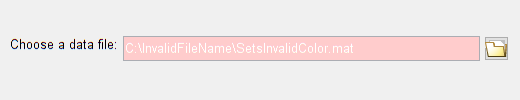

w.Value = 'C:\InvalidFileName\SetsInvalidColor.mat';

To see the widget's behavior in action, look at the demo.

edit demoFileSelector

To see further documentation on this widget, including the available properties and methods, see the automatically generated documentation for the specific widget.

doc uiw.widget.FileSelector

## Using Dialogs

Dialogs may be instantiated as an object as well, however a dialog manages its own figure. When creating the dialog, you may provide the position of a "parent" figure, and the dialog will be centered over the provided position vector.

% Create a list of names
load('patients.mat','LastName');
LastName = sortrows(LastName);

% Launch a dialog to select a name
d = uiw.dialog.SearchList(...
    'Title','Select a patient',...
    'DialogSize',[250 600],...
    'List',LastName);

% Wait for dialog output
[out, action] = d.waitForOutput()

out =      1


action = 'cancel'

## Using Application Superclasses

For building whole applications, Widgets Toolbox provides classes that provide the basic necessities for common types of applications. These include:

- An application window contained within a figure (superclass: uiw.abstract.AppWindow)

- An application window that manages a single session state. The user's session state/data may be saved to disk as a MAT file, and may be loaded back into the application at a later time.(superclass: uiw.abstract.SingleSessionApp)

For usage, please see the demo:

edit demoApp.m

To view the implementation of an app that utilizes this functionality, please view the code within \demo\+demoAppPkg:

cd(fullfile(widgetsRoot,'demo','+demoAppPkg'))

## Using Logger

An important functionality in complex applications, and especially deployed applications, is logging of errors, warnings, and other messages. This is useful for debugging any issues that arise in the software. 

Logging is implemented as a class, and logger objects may be referenced as a singleton by giving a specific name to the logger. 

logName = 'demolog';
log = uiw.tool.Logger(logName,...
    'BufferSize',50,...
    'FileLevel','debug',...
    'DisplayLevel','warning',...
    'Callback',@(h,e)disp(e))

log =   Logger with properties:

            Name: 'demolog'
        Messages: [3×1 uiw.tool.LogMessage]
     LastMessage: [1×1 uiw.tool.LogMessage]
      BufferSize: 50
       FileLevel: DEBUG
    DisplayLevel: WARNING
         LogFile: 'C:\Users\rjackey\AppData\Local\Temp\Log_demolog.txt'
        Callback: @(h,e)disp(e)


Now, add a log message:

log.write('warning','My Warning Message');

	demolog Logger:  WARNING:	My Warning Message
  LogMessage with properties:

      Message: 'My Warning Message'
    Timestamp: 02-Jul-2018 11:08:15
        Level: WARNING
       Source: [0×0 handle]



If you instantiate a logger with the same name from elsewhere in your code, you will have returned the same logger instance. This way, you can have one logger throughout different modules of your software without needing to pass the logger object handle around.

log2 = uiw.tool.Logger(logName);
isequal(log, log2)

ans = logical
   1


For more information, see the documentation for the Logger and LogMessage classes:

doc uiw.tool.Logger
doc uiw.tool.LogMessage

## Making an Application or Custom Widget Loggable

Additionally, if you create a new application or create your own widget by writing a new class definition, you may utilize the class uiw.mixin.HasLogger. Inheriting this class into your own class will provide easy access to the logger and to several methods for logging application-related behaviors or errors. 

For more information, see the documentation for this class:

doc uiw.mixin.HasLogger

## Examples

This toolbox is documented primarily through examples. Please see the Examples library to explore the widgets and components, and the Class Reference for documentation of each widget class.

## Utilities

Please review the Utilities section from the tree on the left for a list of utilities used by various widgets. These utilities may be useful for building custom widgets or other application components.

## Other Classes

In addition to the above, this toolbox also contains additional classes that are shared by various widgets. These can be found in the Class Reference section, and may also be useful for building custom widgets or other application components.

- Base/Abstract Classes

- Mixin Classes

- Enumeration Classes

- Event Classes

## Consulting Support

Are you getting started at building object-oriented apps in MATLAB? [MathWorks Consulting](http://www.mathworks.com/services/consulting) can provide [fee-based advice and coaching ](https://www.mathworks.com/services/consulting/proven-solutions/software-development-with-matlab.html)to help you get started.

© 2018 The MathWorks, Inc.